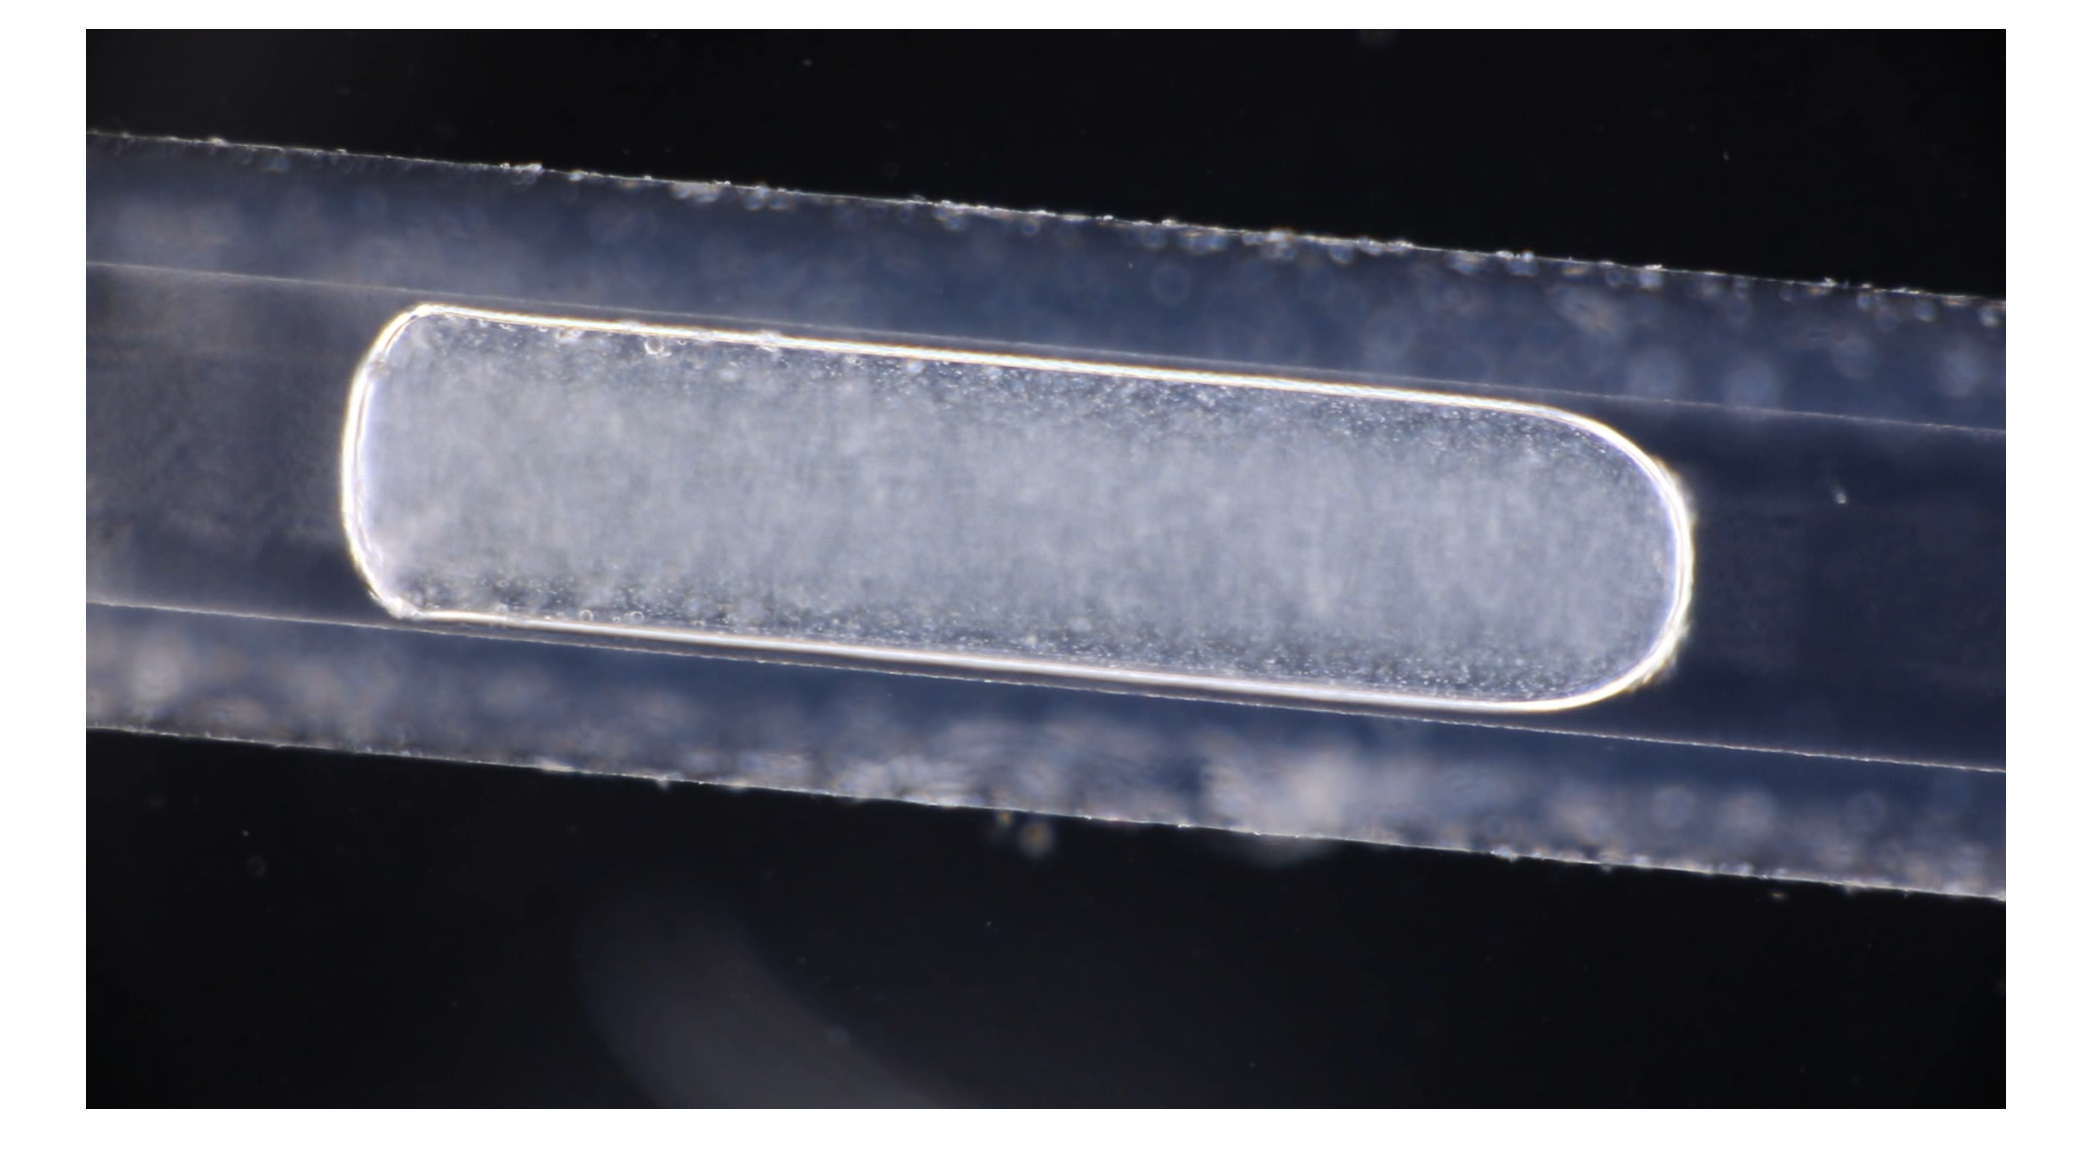

%% Testing Droplet Properties
clear, clc, close all;

% Read Image
i1 = imread('goodDrop.png');
figure, imshow(i1);

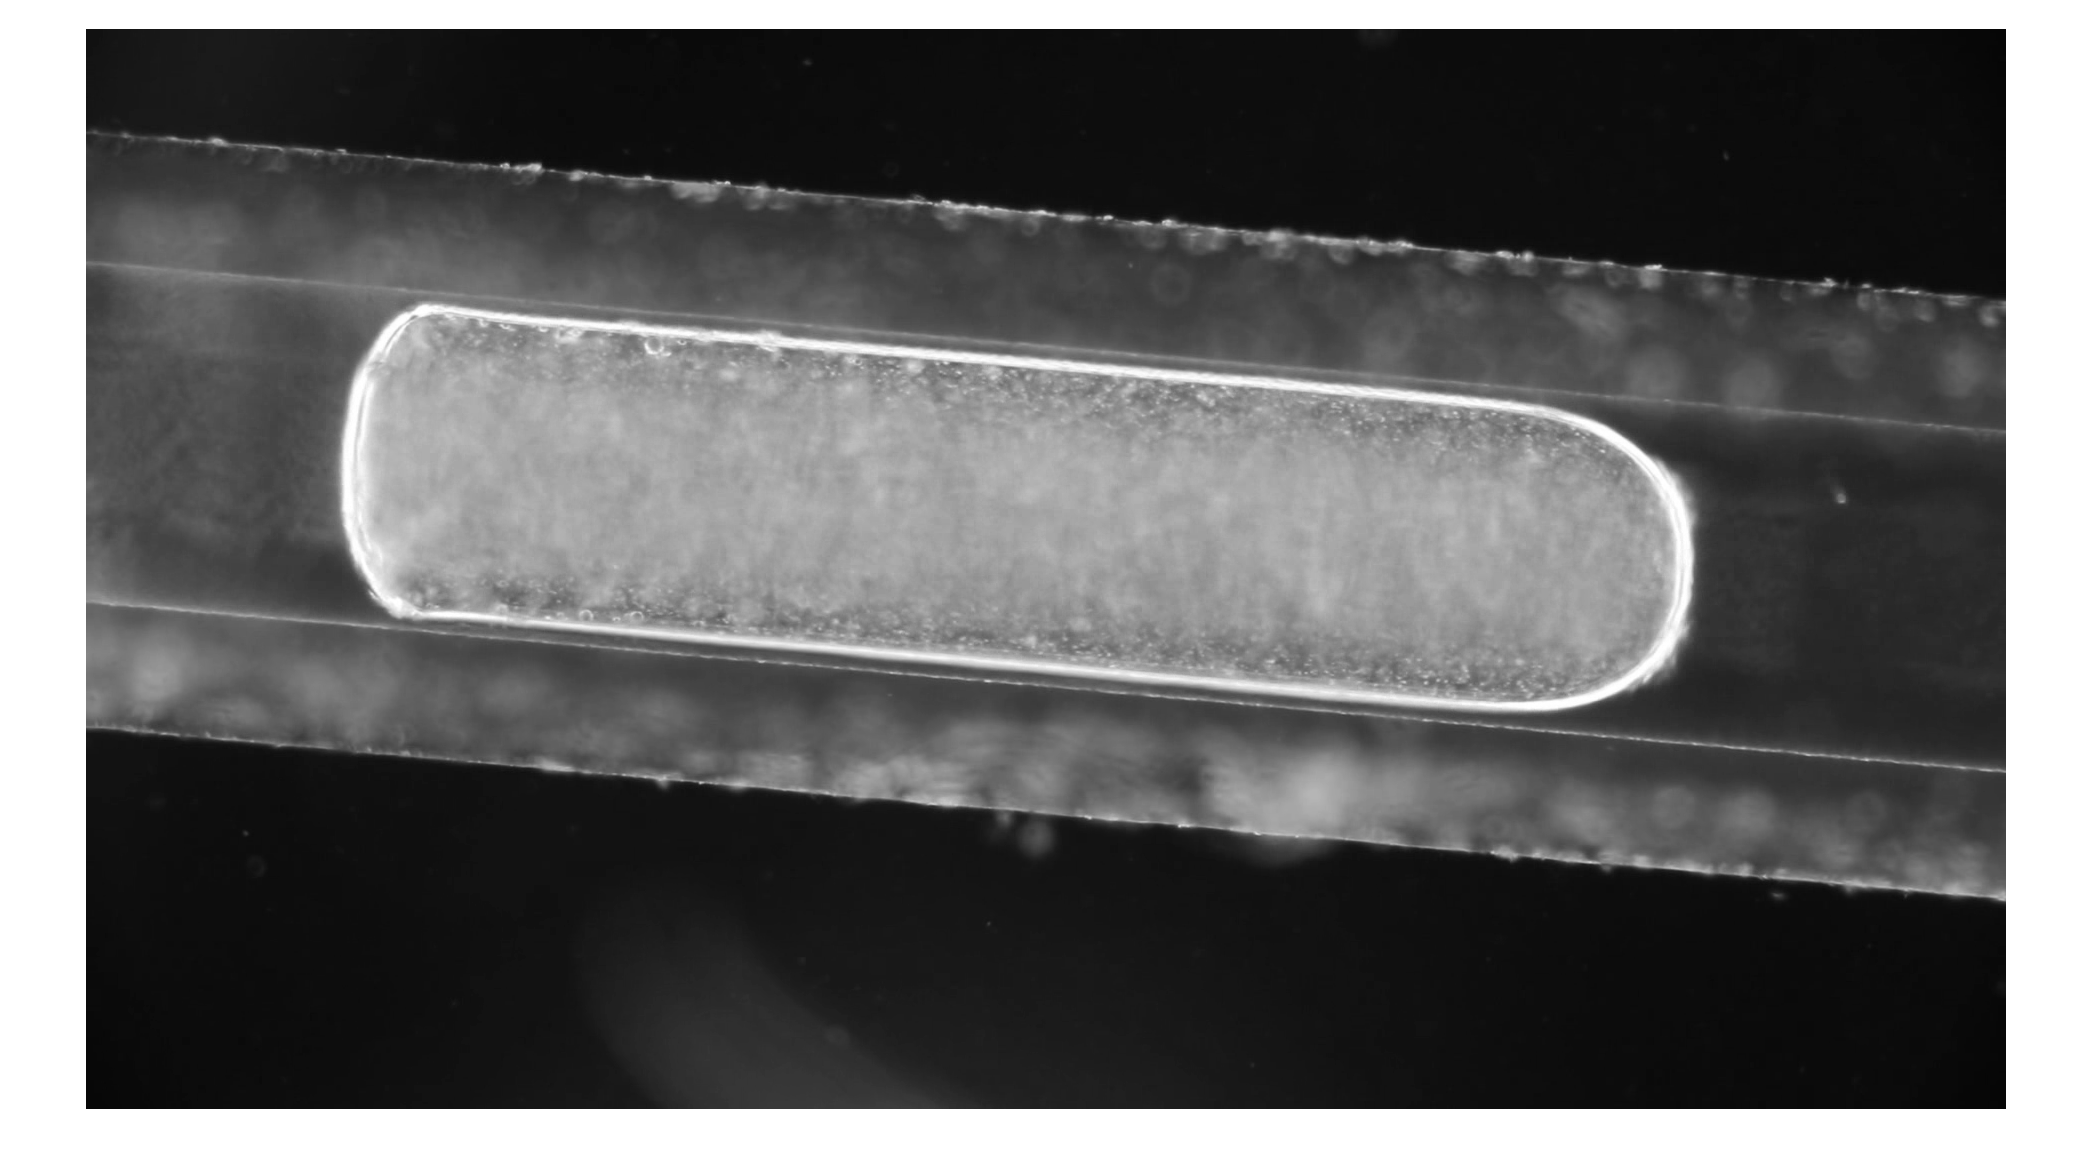


% Convert to Gray Scale
i1G = rgb2gray(i1);
figure, imshow(i1G);

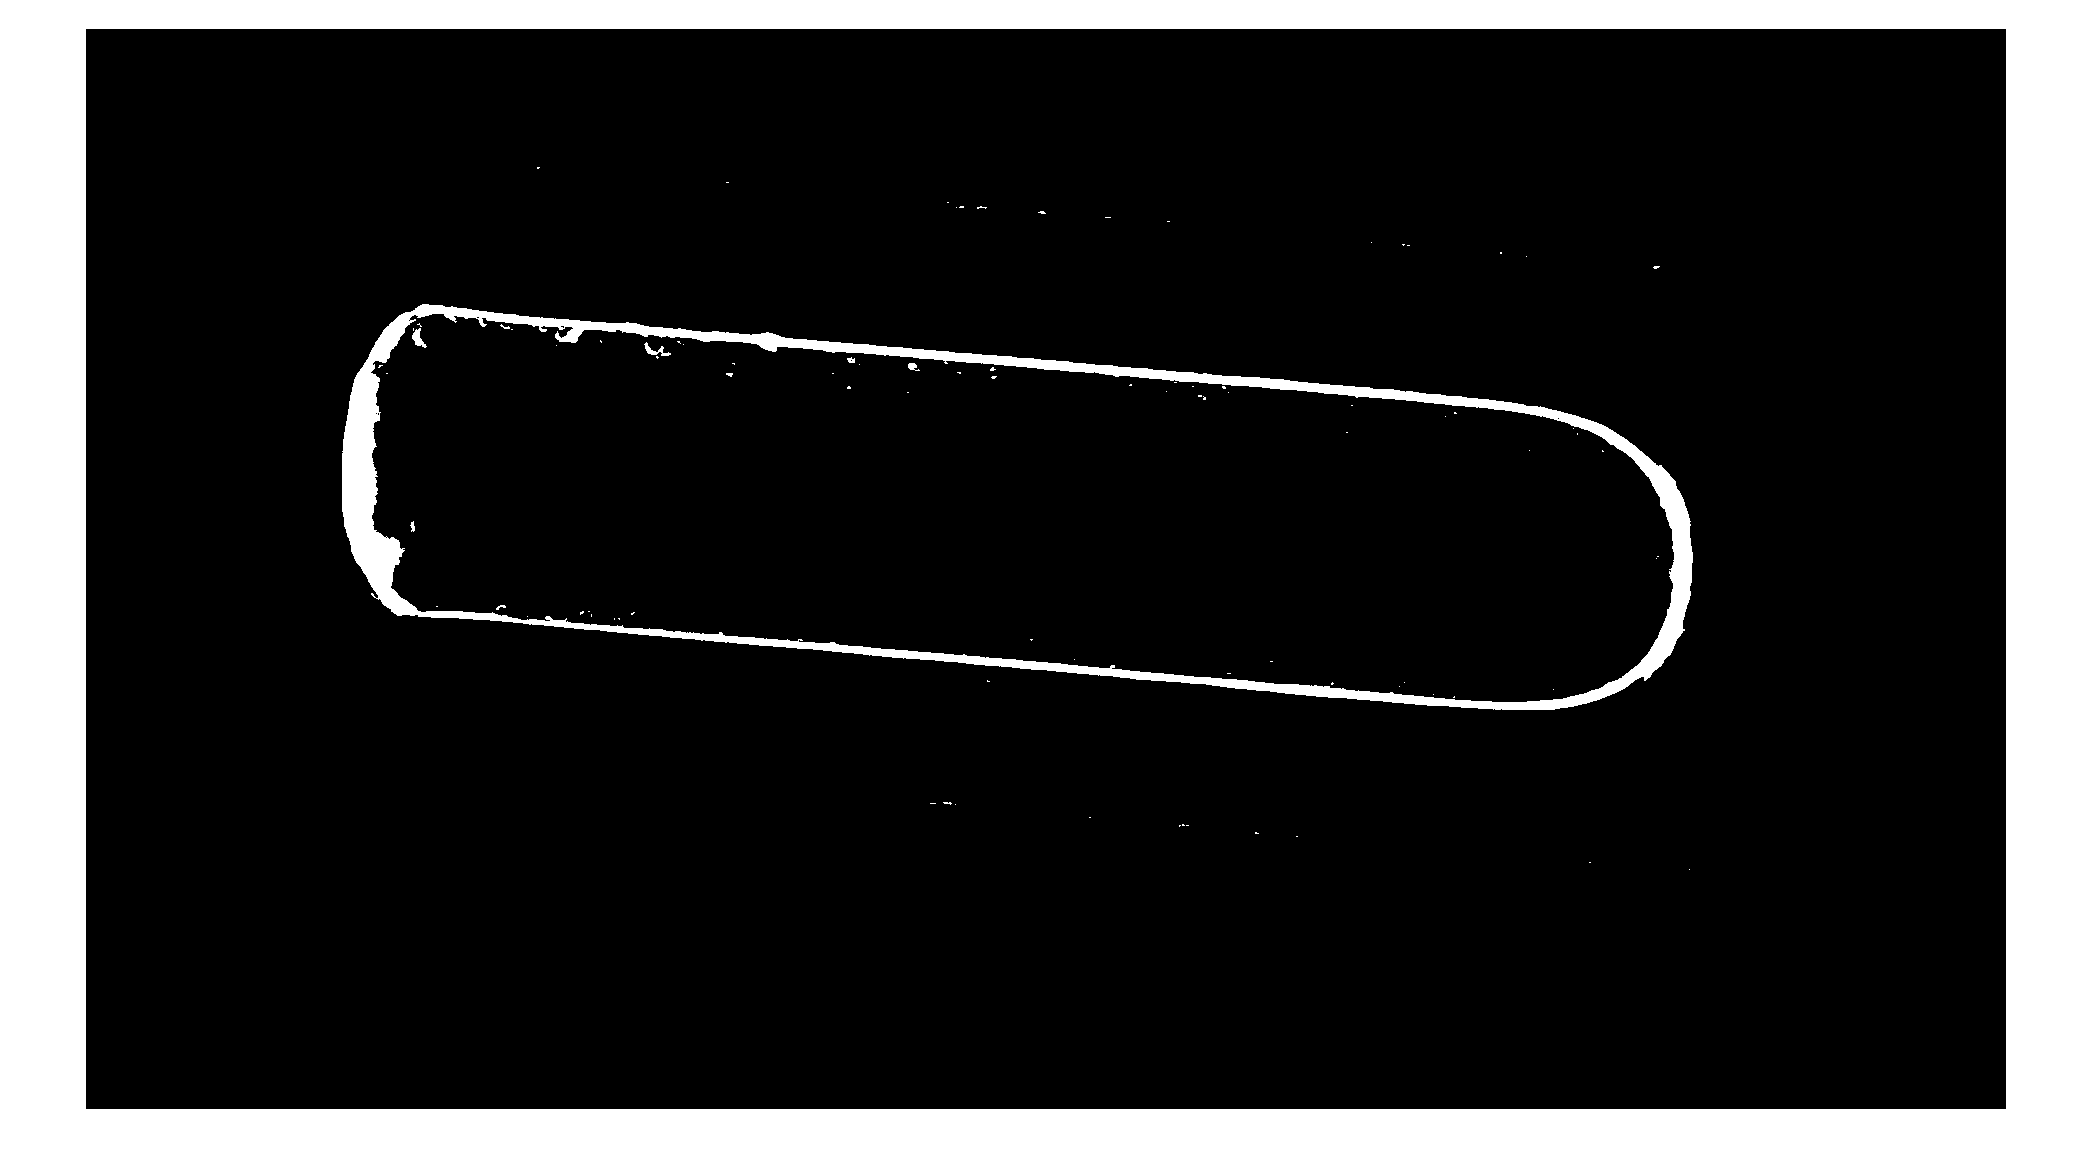


% Convert to Logical
i1BW = im2bw(i1G,195/255);
figure, imshow(i1BW);

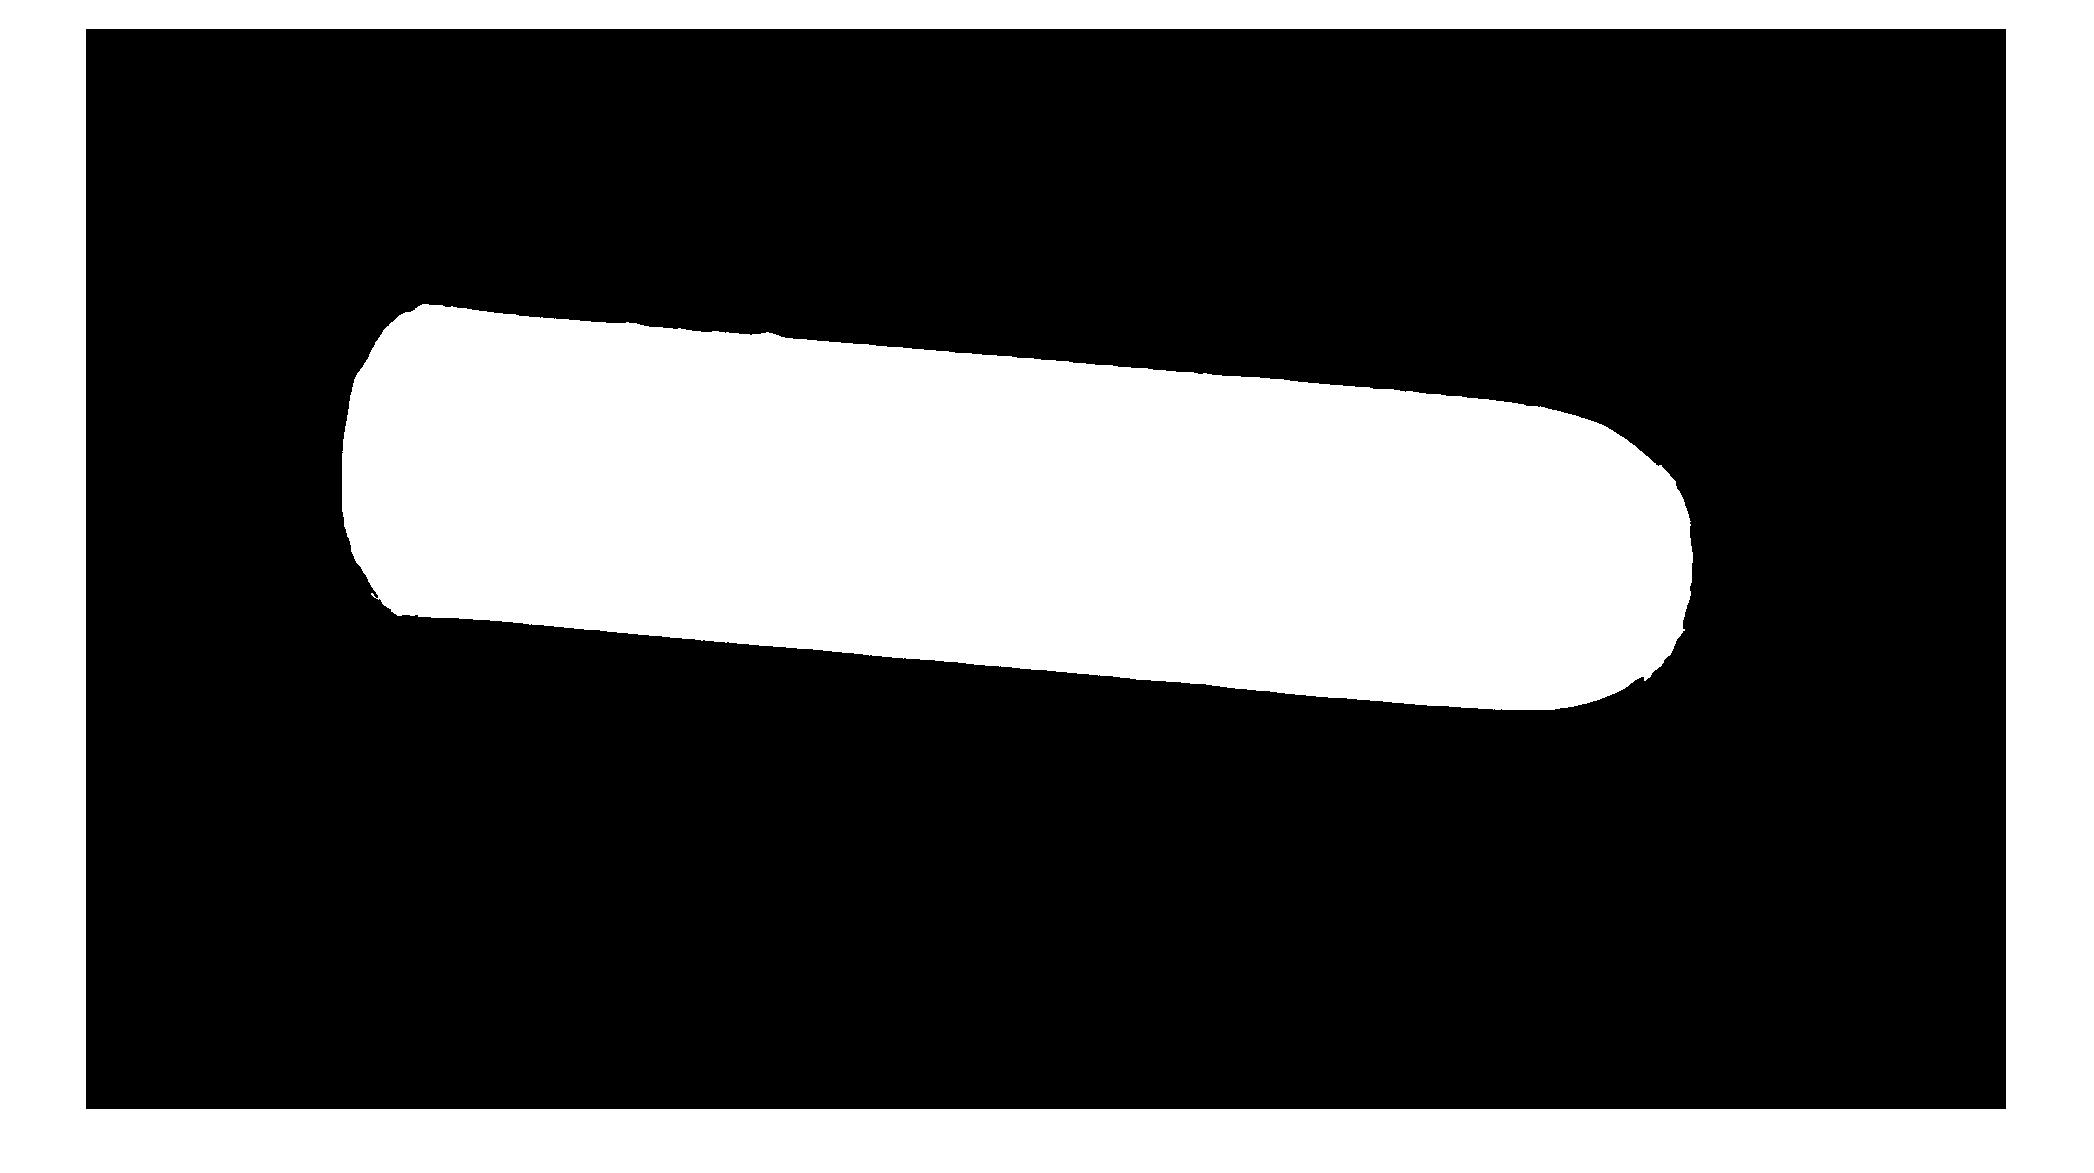


% Fill Logical Image and Create Label
filledIm = imfill(i1BW,'holes');
filledLabel = bwlabel(filledIm);

% Get Region Properties and Isolate Droplet Label
fillProps = regionprops(filledLabel,"all");
areaMax = max(sort([fillProps.Area],'descend'));
[~,indexMax] = max([fillProps.Area] == areaMax);
filledLabel(filledLabel ~= indexMax) = 0;
filledLabel = logical(filledLabel);
figure, imshow(filledLabel);

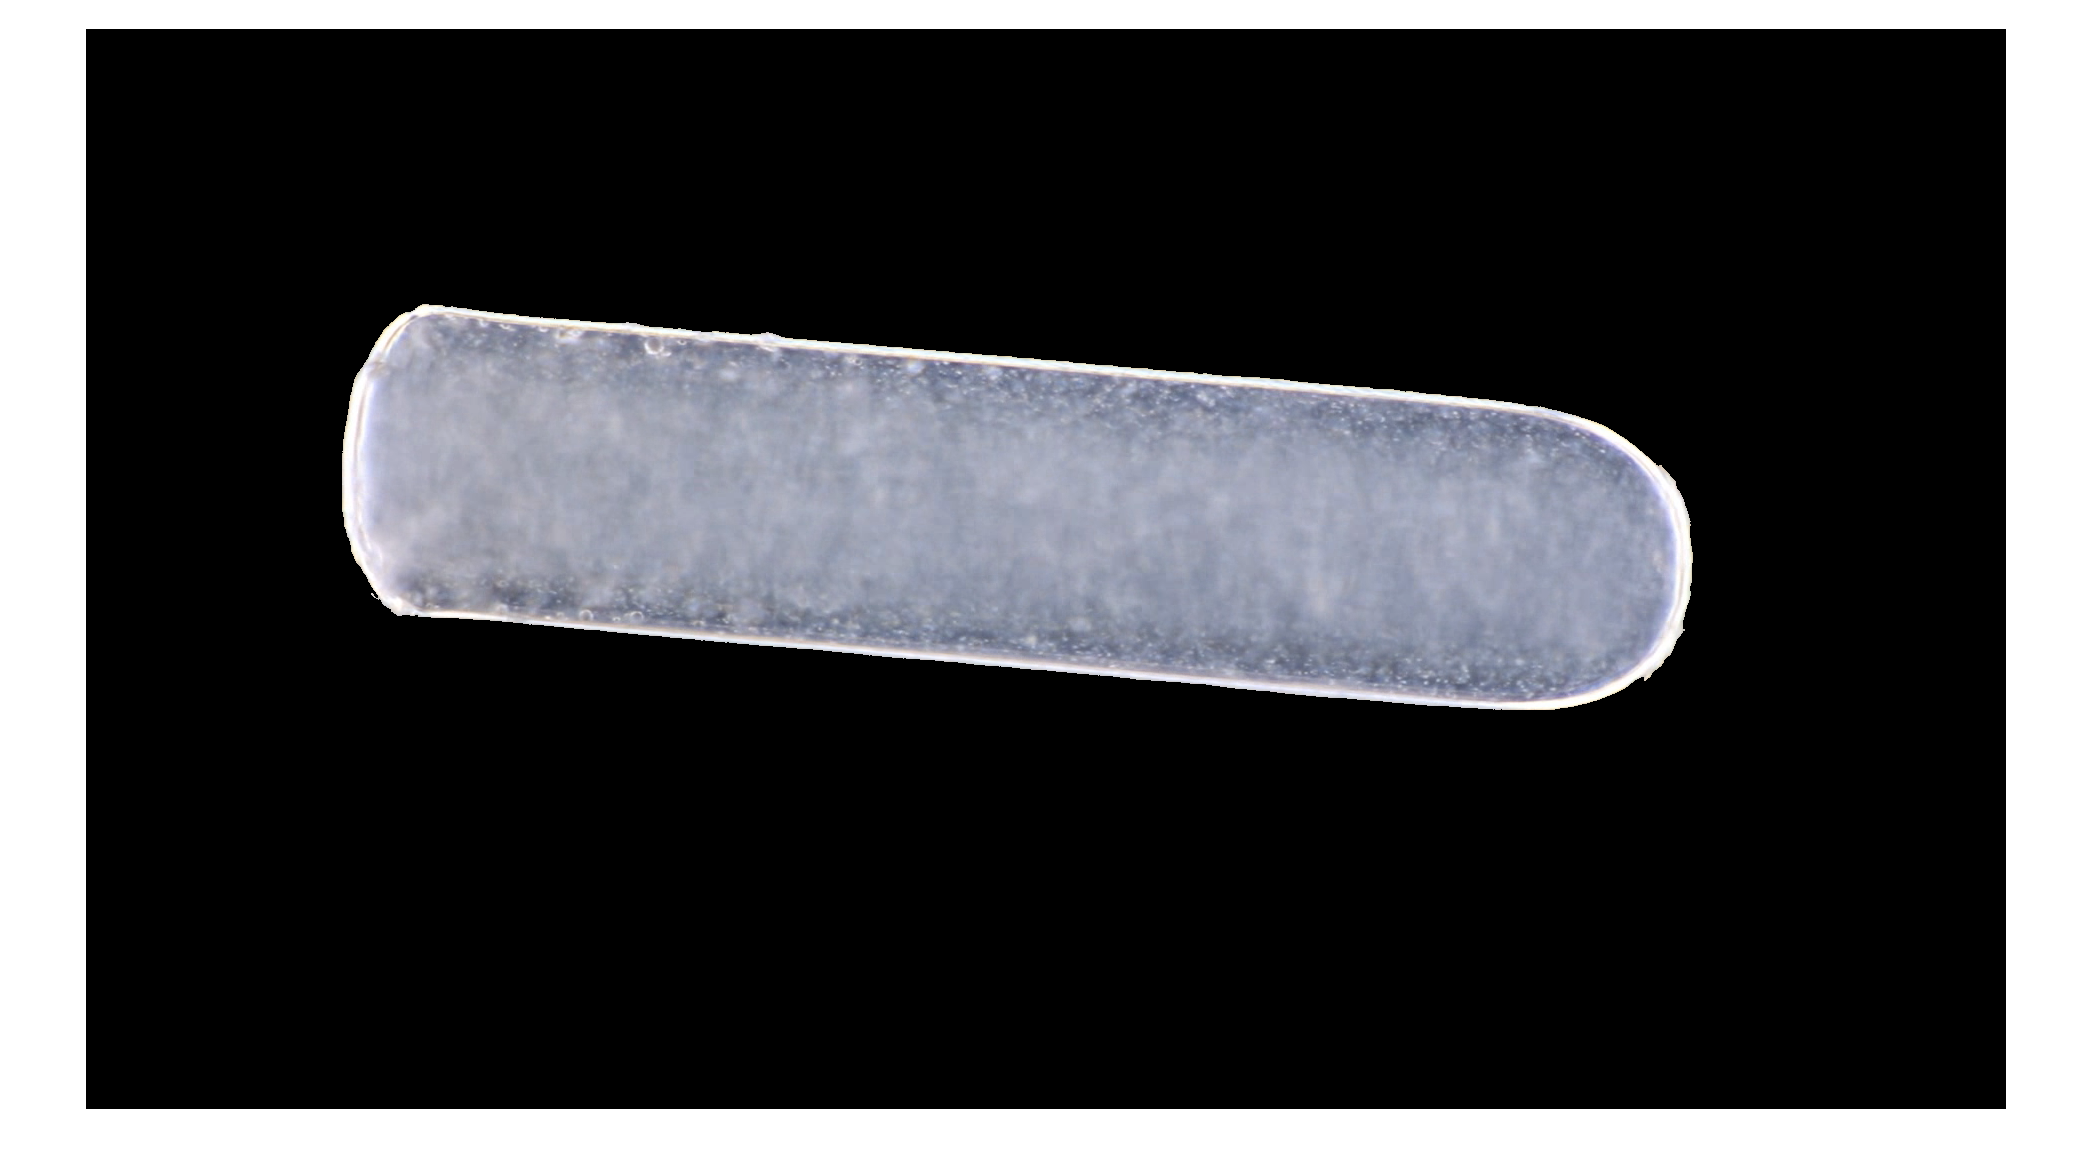


% Isolate Droplet from Original Image
filledLabel = 255*uint8(filledLabel);
droplet = bitand(i1,filledLabel);
figure, imshow(droplet);